# Runtime optimization

## Plot runtime plot

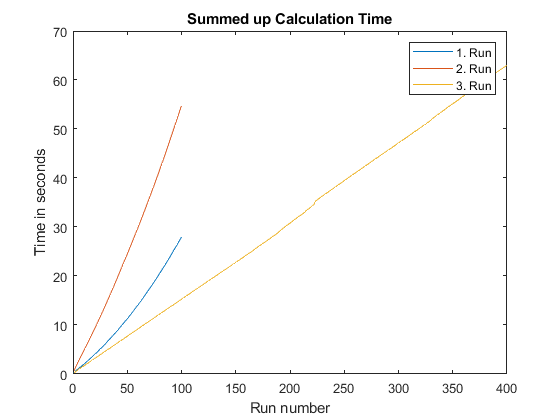

% Opens save files with the coresponding names
Result = open('CarSetup2_result.mat');
Result_2 = open('CarSetup3_result.mat');
% Result_3 = open('CarSetup4_result.mat');
Result_3 = open('CarSetupT1_result.mat');

% Draws calculation time plot
figure(1)
plot(Result.tEnd)
hold on;
plot(Result_2.tEnd)
hold on;
plot(Result_3.tEnd)
hold off;

title('Summed up Calculation Time')
xlabel('Run number')
ylabel('Time in seconds')
legend('1. Run', '2. Run', '3. Run')

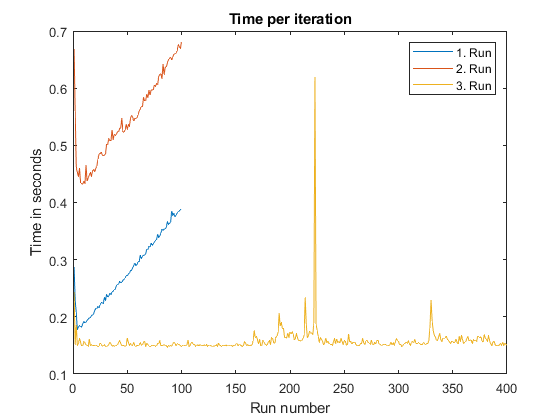


% Calculate runtime per run
timeRun = zeros(1,length(Result.tEnd));
sumTime = 0;

for i = 1:length(Result.tEnd)
    timeRun(i) = Result.tEnd(i) - sumTime;
    sumTime = Result.tEnd(i);
end

% Calculate runtime per run
timeRun_2 = zeros(1,length(Result.tEnd));
sumTime_2 = 0;

for i = 1:length(Result_2.tEnd)
    timeRun_2(i) = Result_2.tEnd(i) - sumTime_2;
    sumTime_2 = Result_2.tEnd(i);
end

% Calculate runtime per run
timeRun_3 = zeros(1,length(Result.tEnd));
sumTime_3 = 0;

for i = 1:length(Result_3.tEnd)
    timeRun_3(i) = Result_3.tEnd(i) - sumTime_3;
    sumTime_3 = Result_3.tEnd(i);
end

% Draws plot with time per run
figure(2)
plot(timeRun)
hold on;
plot(timeRun_2)
hold on;
plot(timeRun_3)
title('Time per iteration')
xlabel('Run number')
ylabel('Time in seconds')
legend('1. Run', '2. Run', '3. Run')